# Proyecto Final de Control

## Control de giro y guiñada de un avión comercial

Se cuenta con las ecuaciones que definen el comportamiento del sistema, teniendo en cuenta algunas restricciones se tiene el modelo lateral desacoplado del avión. Para los parámetros se usan los datos de un avión Boeing B-747 (Heffley y Jewell, 1972).

%Derivadas de las variables de estado_
beta_p = sym('beta_p');
p_p = sym('p_p');
r_p = sym('r_p');
phi_p = sym('phi_p');
psi_p = sym('psi_p');
x_p = [beta_p, p_p, r_p, phi_p, psi_p]

$$x\_p = \left(\begin{array}{ccccc} \beta_{p} & p_{p} & r_{p} & \varphi_{p} & \psi_{p} \end{array}\right)$$

%Variables de estado_
beta = sym('beta');
p = sym('p');
r = sym('r');
phi = sym('phi');
psi = sym('psi');
x = [beta, p, r, phi, psi]

$$x = \left(\begin{array}{ccccc} \beta & p & r & \varphi & \psi \end{array}\right)$$

%Entradas del sistema
delta_a =sym('delta_a');
delta_r =sym('delta_r');
u = [delta_a, delta_r]

$$u = \left(\begin{array}{cc} \delta_{a} & \delta_{r} \end{array}\right)$$

## Espacio de Estados

Para el espacio de estados, se tiene como entradas a los ángulos de alerón y de timón ($\delta_{a\;} y\;\delta_r$). Como salida, se tienen los ángulos de roll (giro) y de yaw (guiñada). 

%Matriz A
A = [-0.0558 0.08 -0.997 0.0415 0.0033;
    -3.05 -0.465 0.388 0 0;
    0.598 -0.318 -0.115 0 0;
    0 1 0 0 0;
    0 0 1 0 0]

A =    -0.0558    0.0800   -0.9970    0.0415    0.0033
   -3.0500   -0.4650    0.3880         0         0
    0.5980   -0.3180   -0.1150         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0


%Matriz B
B = [0 0.00729;
    0.143 0.153;
    0.00775 -0.475;
    0 0;
    0 0]

B =          0    0.0073
    0.1430    0.1530
    0.0077   -0.4750
         0         0
         0         0


%Matriz C
C = [0 0 0 1 0;
    0 0 0 0 1]

C =      0     0     0     1     0
     0     0     0     0     1


%Matriz D
D = [0 0;0 0]

D =      0     0
     0     0


## Comportamiento a lazo abierto

Para entradas de $\delta_a =$ y $\delta_r =$ se analiza el comportamiento del sistema y se observa la salida del mismo.

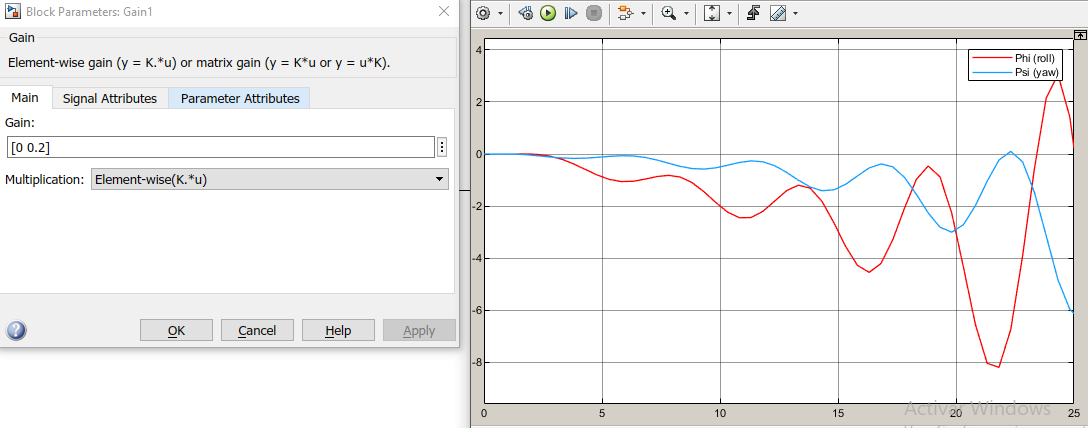

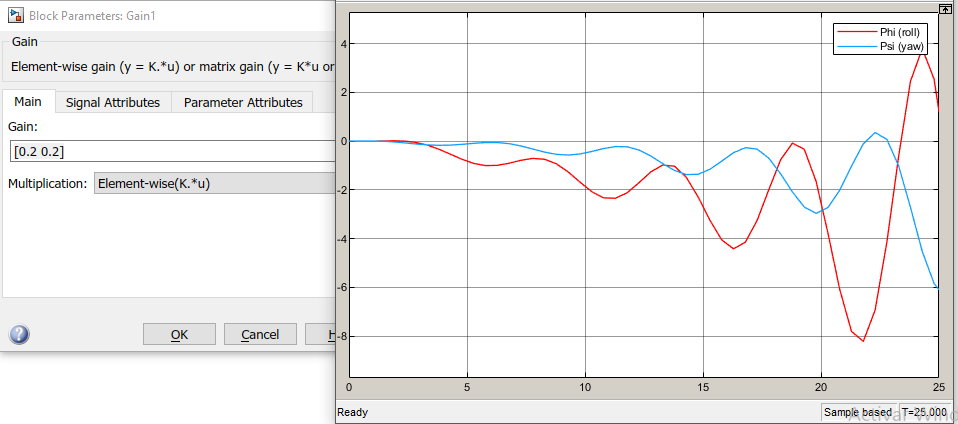

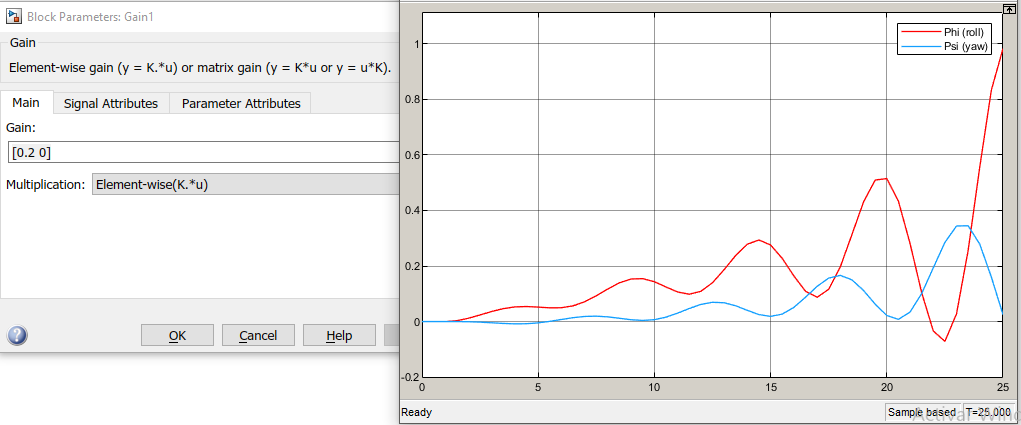

## Controlabilidad

Se mide la controlabilidad en el sistema. Para la misma se usa la matriz de controlabilidad. Primero se obtiene la Función de transferencia de la planta para saber el rango de la misma.

%Una prueba para cada entrada, el denominador (a) es el mismo
[b1,a1] = ss2tf(A,B,C,D,1)

b1 =          0         0    0.1430    0.0274    0.1099   -0.0004
         0         0    0.0077   -0.0414    0.0064    0.0045


a1 =     1.0000    0.6358    1.0494    1.3882    0.0008   -0.0000


[b2,a2] = ss2tf(A,B,C,D,2)

b2 =          0         0    0.1530   -0.1804   -1.3634    0.0045
         0         0   -0.4750   -0.2917   -0.1145   -0.0563


a2 =     1.0000    0.6358    1.0494    1.3882    0.0008   -0.0000


Se obtuvieron los polos a lazo abierto del sistema,

Como el mayor coeficiente del denominador es de orden 5, quiere decir que la planta es de orden 5.

La matriz de controlabilidad de Kalman tiene la siguiente forma:


$$Q=\left\lbrack \begin{array}{ccccc}
B & \textrm{AB} & A^2 B & \ldotp \ldotp \ldotp  & A^{n-1} B
\end{array}\right\rbrack$$


%Q = [B A*B A^2*B A^3*B A^4*B];
Q = ctrb(A,B)

Q =          0    0.0073    0.0037    0.4854    0.0469   -0.0548   -0.0330   -0.4925   -0.0334   -0.3032
    0.1430    0.1530   -0.0635   -0.2777    0.0002   -1.3474   -0.1324    0.9401    0.1720    1.2016
    0.0077   -0.4750   -0.0464    0.0103    0.0277    0.3774    0.0248    0.3523    0.0195   -0.6340
         0         0    0.1430    0.1530   -0.0635   -0.2777    0.0002   -1.3474   -0.1324    0.9401
         0         0    0.0077   -0.4750   -0.0464    0.0103    0.0277    0.3774    0.0248    0.3523


fprintf("El rango es %d", rank(Q))

El rango es 5

Como la matriz es de rango 5, igual al orden de la planta, entonces la misma es controlable.

## Observabilidad

Se analizará la observabilidad del sistema. Por lo general hay variables de estado que no pueden medirse, por lo tanto se deben estimar los estados. Para colocar un observador primero debo analizar la observabilidad del sistema.

Ob = obsv(A,C);
if rank(Ob)== 5
    fprintf("El sistema es observable")
end

El sistema es observable

Dado que el rango del sistema es igual a la cantidad de estados, entonces se dice que el sistema es observable.

## Control LQI

### Control LQR

Se plantean las matrices Q y R.

q_i = 0.95;  %el peso para la matriz Q
rho_i = 1;
Q = q_i*eye(5);
%R = rho_i*eye(2);
R = [.95 0; 0 1];

%Obtención de las ganancias optimizadas
[K, S, P] = lqr(A,B,Q,R)

K =    -0.5745    0.3714    0.3861    0.2894    0.2163
    3.0566   -0.6272   -4.4557   -0.7916   -1.0224


S =    34.7196   -3.4367   -7.0090   -2.9372   21.1684
   -3.4367    2.3577    2.0270    1.8030    1.2801
   -7.0090    2.0270    9.9259    2.2023    2.8896
   -2.9372    1.8030    2.2023    2.5149    0.5495
   21.1684    1.2801    2.8896    0.5495   25.5985


P =   -0.0417 + 0.0000i
  -0.5121 + 1.3021i
  -0.5121 - 1.3021i
  -0.7024 + 0.0000i
  -0.9665 + 0.0000i


Acl = A-B*K

Acl =    -0.0781    0.0846   -0.9645    0.0473    0.0108
   -3.4355   -0.4222    1.0145    0.0797    0.1255
    2.0543   -0.6188   -2.2345   -0.3783   -0.4873
         0    1.0000         0         0         0
         0         0    1.0000         0         0


inv(Acl)

ans =    -0.1555   -0.3423   -0.0916   -0.1880   -0.0073
         0         0         0    1.0000         0
         0         0         0         0    1.0000
   25.5603   -0.2880    0.4898   -1.9802   26.0401
  -20.4959   -1.2195   -2.8184   -0.5254  -24.8291


Veo si el sistema a lazo cerrado es estable

 syscl = ss(Acl,B,C,D)

syscl =
 
  A = 
             x1        x2        x3        x4        x5
   x1  -0.07808   0.08457   -0.9645   0.04727   0.01075
   x2    -3.436   -0.4222     1.015   0.07974    0.1255
   x3     2.054   -0.6188    -2.234   -0.3783   -0.4873
   x4         0         1         0         0         0
   x5         0         0         1         0         0
 
  B = 
            u1       u2
   x1        0  0.00729
   x2    0.143    0.153
   x3  0.00775   -0.475
   x4        0        0
   x5        0        0
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   0   0   1   0
   y2   0   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



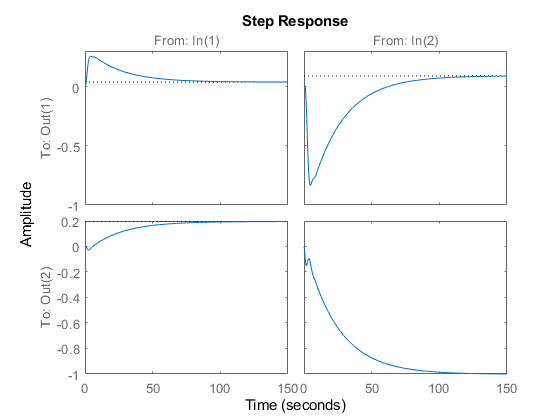

 step(syscl)

 %Kdc = dcgain(syscl)
 %Kr = 1\Kdc
% sysclscaled = ss(Acl,B*Kr,C,D);
% step(sysclscaled)

Para q_i=1 y rho=1 el sistema tiene el siguiente comportamiento:

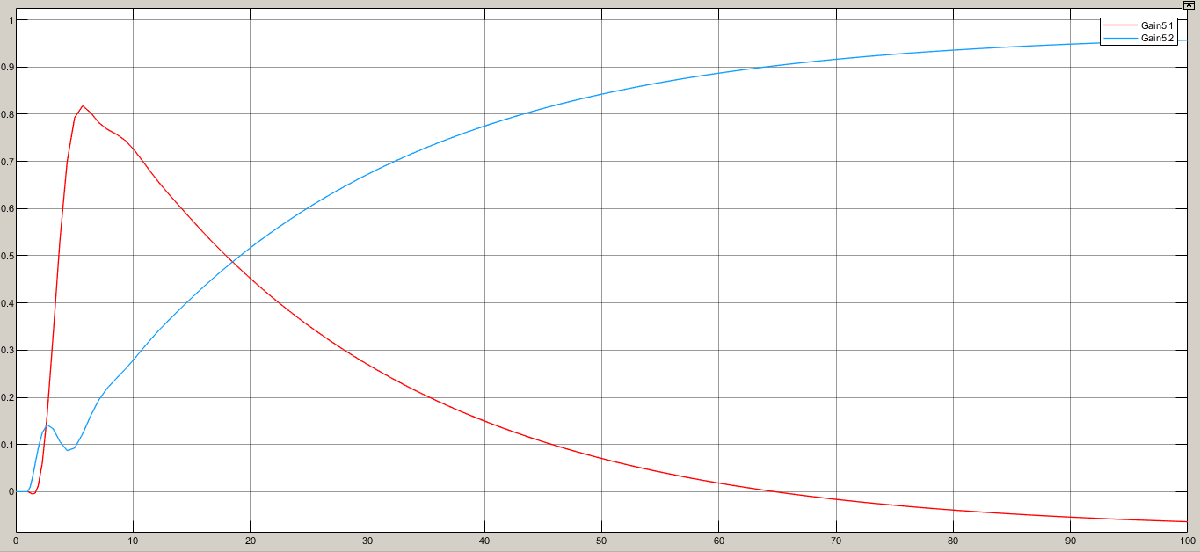

Podemos ver que es un error de estado estacionario.

Para q_i=0.95 y R = [0.95 0; 0 1]:

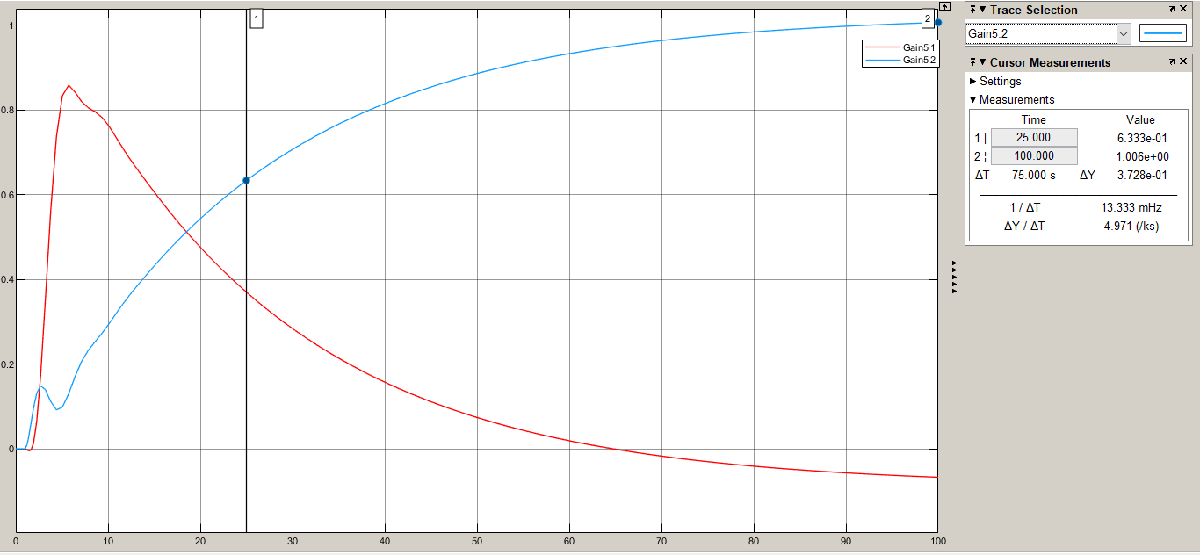

Usando la regla de Bryson, voy a dar a cada coeficiente los valores. Para los $a_i =\sqrt{0,20}$ y $\rho_i =\sqrt{0,50}$. Los valores máximos de error de cada componente serán: $\beta =0,05\;\textrm{rad},p=1,\;r=1,\psi =0,1\;\textrm{rad},\phi =0,1\;\textrm{rad}$. Para la matriz de costos R ($\left.Q_u \right)\;$se dan inicialmente valores iguales a 1 a los costos, entonces las matrices serán:

a_i = sqrt(0.2);
rho_i = sqrt(0.001);%0.5
Q = [a_i^2/0.5^2 0 0 0 0;
    0 a_i^2/10 0 0 0;
    0 0 a_i^2/10 0 0;
    0 0 0 a_i^2/.1^2 0;
    0 0 0 0 a_i^2/.1^2];
R = [rho_i^2/10 0;
    0 rho_i^2/10];
%Obtención de las ganancias optimizadas
[K, S, P] = lqr(A,B,Q,R)

K =   -12.2022   75.0321   23.3462  438.2732   94.5294
    8.6926    4.5658  -45.3443   85.9017 -437.8074


S =     9.2888   -0.0159    0.1356   -0.6476    9.2595
   -0.0159    0.0516    0.0154    0.3027    0.0525
    0.1356    0.0154    0.0166    0.0695    0.2512
   -0.6476    0.3027    0.0695    3.5430   -0.1270
    9.2595    0.0525    0.2512   -0.1270   11.4457


P =   -0.0442 + 0.0000i
  -5.6876 + 5.4353i
  -5.6876 - 5.4353i
 -11.2137 +10.1111i
 -11.2137 -10.1111i


Acl = A-B*K

Acl =    -0.1192    0.0467   -0.6664   -0.5847    3.1949
   -2.6350  -11.8932    3.9872  -75.8160   53.4668
    4.8216    1.2693  -21.8345   37.4067 -208.6911
         0    1.0000         0         0         0
         0         0    1.0000         0         0


 syscl = ss(Acl,B,C,D)

syscl =
 
  A = 
            x1       x2       x3       x4       x5
   x1  -0.1192  0.04672  -0.6664  -0.5847    3.195
   x2   -2.635   -11.89    3.987   -75.82    53.47
   x3    4.822    1.269   -21.83    37.41   -208.7
   x4        0        1        0        0        0
   x5        0        0        1        0        0
 
  B = 
            u1       u2
   x1        0  0.00729
   x2    0.143    0.153
   x3  0.00775   -0.475
   x4        0        0
   x5        0        0
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   0   0   1   0
   y2   0   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



 %step(syscl)
 %Kdc = dcgain(syscl)
 %Kr = 1\Kdc
 Kr = -inv(C*inv(Acl)*B)

Kr =   445.2419   95.0836
   95.5274 -437.0420


% sysclscaled = ss(Acl,B*Kr,C,D);
% step(sysclscaled)

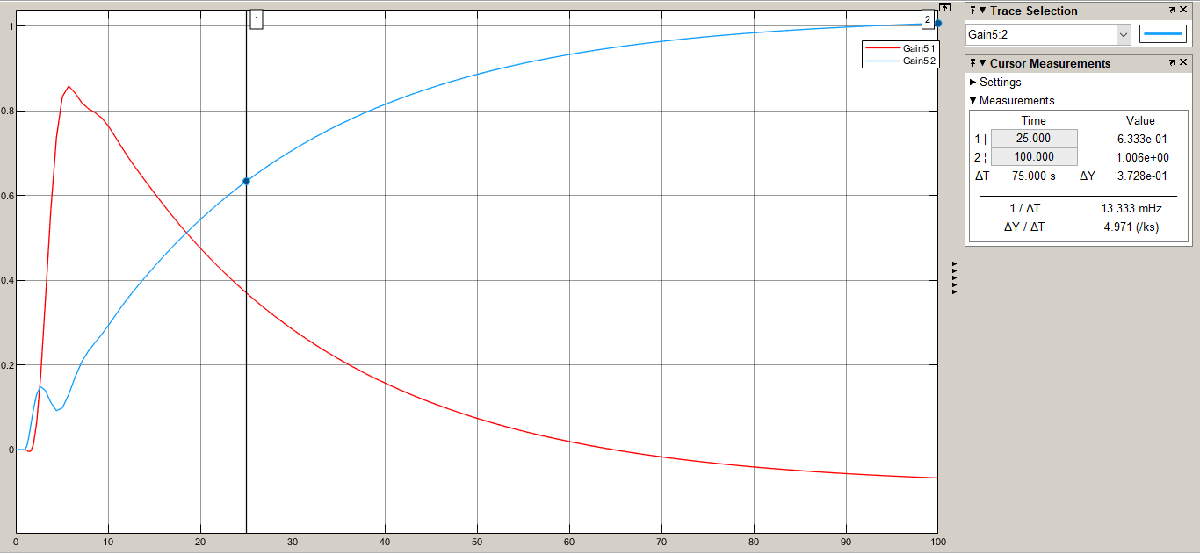

Habiendo corregido el valor de Kr, se obtienen los siguientes valores:

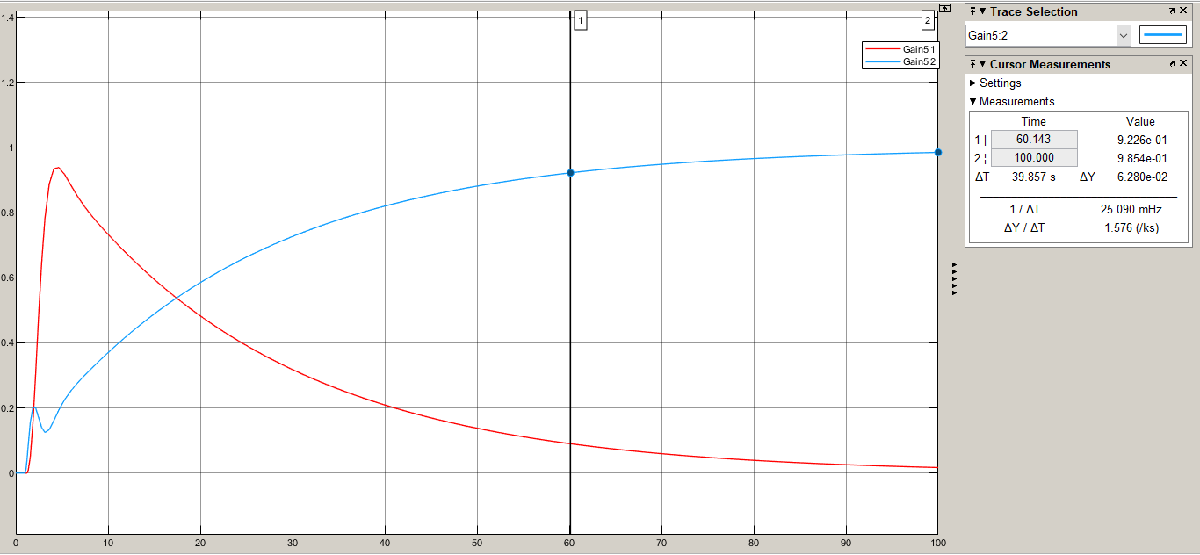

Sigue habiendo error de estado estacionario pero no se pasa del valor consigna. La respuesta es muy lenta. Se modifican los valores de las ganancias individuales de Q y de R. La respuesta se ve en la siguiente imagen:

Q = [a_i^2/0.5^2 0 0 0 0;

    0 a_i^2/10 0 0 0;

    0 0 a_i^2/10 0 0;

    0 0 0 a_i^2/.1^2 0;

    0 0 0 0 a_i^2/.1^2];

R = [rho_i^2/10 0;

    0 rho_i^2/10];

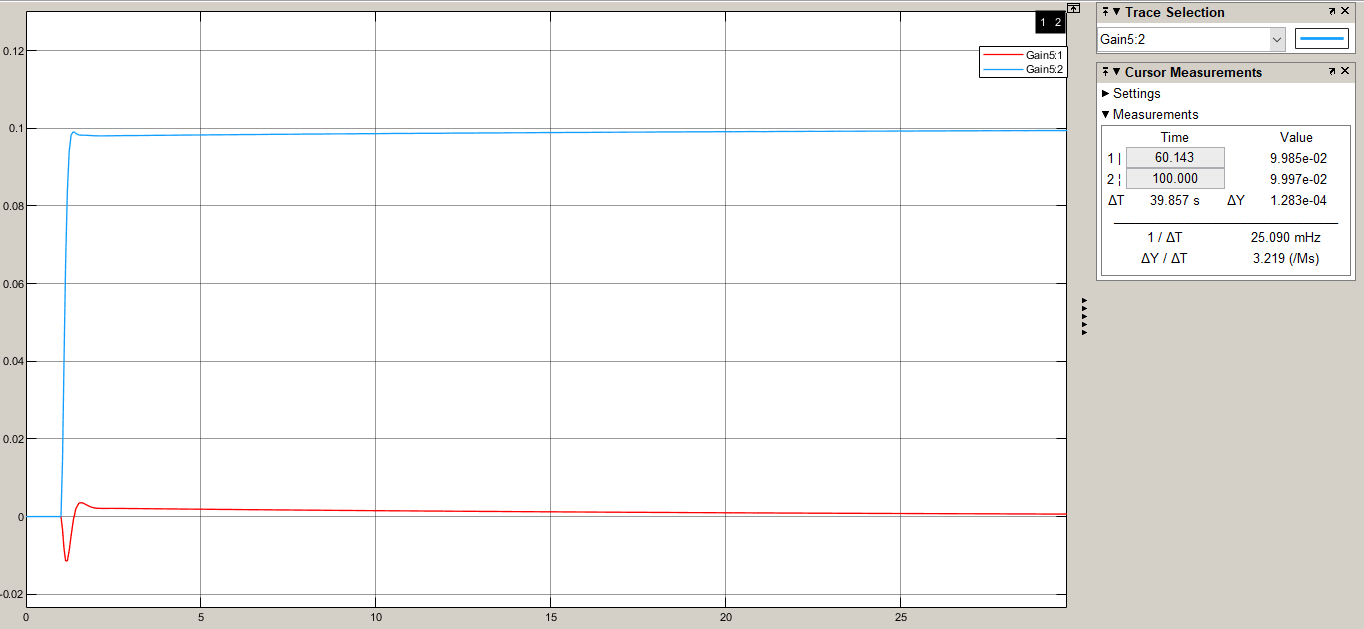

Para otra consigna:

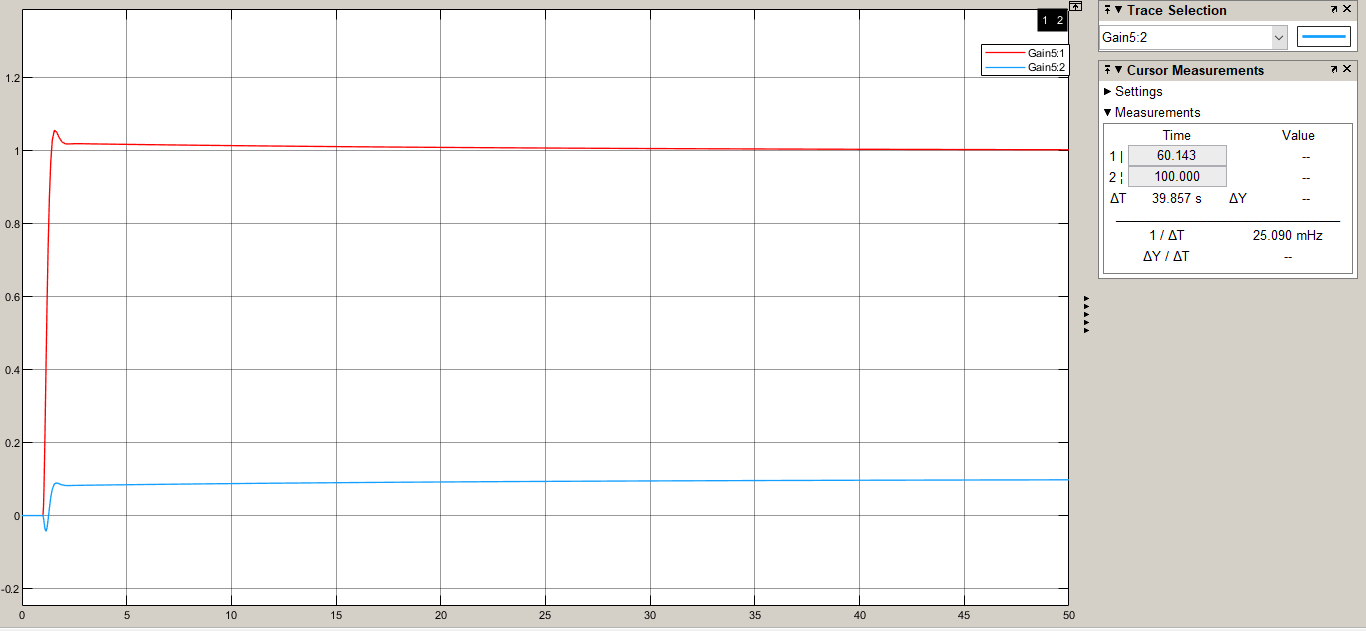

Al agregar un integrador se resuelve el problema del error de estado estacionario. Se debe agregar otro estado para definir el sistema, el mismo quedará con la siguiente forma (Ogata):

Se obtienen las matrices para el sistema aumentado.

aaug = [0 0 0 0 0;
        0 0 0 0 0]';
caug = [0 0; 0 0]';
baug = [0 0;
        0 0];
Aaug = [A aaug;
    -C caug]

Aaug =    -0.0558    0.0800   -0.9970    0.0415    0.0033         0         0
   -3.0500   -0.4650    0.3880         0         0         0         0
    0.5980   -0.3180   -0.1150         0         0         0         0
         0    1.0000         0         0         0         0         0
         0         0    1.0000         0         0         0         0
         0         0         0   -1.0000         0         0         0
         0         0         0         0   -1.0000         0         0


Baug = [B; baug]

Baug =          0    0.0073
    0.1430    0.1530
    0.0077   -0.4750
         0         0
         0         0
         0         0
         0         0


Caug = [C caug]

Caug =      0     0     0     1     0     0     0
     0     0     0     0     1     0     0



a_i = sqrt(0.1428);
rho_i = sqrt(0.5);%0.001
%Se hacen a las matrices diagonales porque ambas salidas están desacopladas
Qaug = [a_i^2/0.5^2 0 0 0 0 0 0;
    0 a_i^2/10 0 0 0 0 0;
    0 0 a_i^2/10 0 0 0 0;
    0 0 0 a_i^2/.1^2 0 0 0;
    0 0 0 0 a_i^2/.1^2 0 0;
    0 0 0 0 0 a_i^2/.1^2 0;
    0 0 0 0 0 0 a_i^2/.1^2];

Raug = [rho_i^2/10 0;
    0 rho_i^2/10];
QQ = ctrb(Aaug, Baug)

QQ =          0    0.0073    0.0037    0.4854    0.0469   -0.0548   -0.0330   -0.4925   -0.0334   -0.3032   -0.0092    0.7853    0.0867    0.5026
    0.1430    0.1530   -0.0635   -0.2777    0.0002   -1.3474   -0.1324    0.9401    0.1720    1.2016    0.0293    0.1201   -0.0154   -2.6413
    0.0077   -0.4750   -0.0464    0.0103    0.0277    0.3774    0.0248    0.3523    0.0195   -0.6340   -0.0769   -0.4905   -0.0060    0.4878
         0         0    0.1430    0.1530   -0.0635   -0.2777    0.0002   -1.3474   -0.1324    0.9401    0.1720    1.2016    0.0293    0.1201
         0         0    0.0077   -0.4750   -0.0464    0.0103    0.0277    0.3774    0.0248    0.3523    0.0195   -0.6340   -0.0769   -0.4905
         0         0         0         0   -0.1430   -0.1530    0.0635    0.2777   -0.0002    1.3474    0.1324   -0.9401   -0.1720   -1.2016
         0         0         0         0   -0.0077    0.4750    0.0464   -0.0103   -0.0277   -0.3774   -0.0248   -0.3523   -0.0195    0.6340



rank(QQ)

ans = 7

%Obtención de las ganancias optimizadas
[Kaug, Saug, Paug] = lqr(Aaug,Baug,Qaug,Raug)

Kaug =   -19.0520   15.1014    6.4883   29.5407   -5.2930  -16.4953    3.6748
   -1.2464   -5.6529  -13.1541   -8.9659  -32.3421    3.6748   16.4953


Saug =   225.3219   -6.7384    1.4188  -20.6573  227.4579    9.5481   -8.6360
   -6.7384    5.1634    2.1548   10.1183   -2.1862   -5.6558    1.3624
    1.4188    2.1548    2.1005    3.8859    6.1911   -2.0621   -1.4301
  -20.6573   10.1183    3.8859   27.0566  -10.7150  -17.5433   -1.0180
  227.4579   -2.1862    6.1911  -10.7150  246.4554    3.7086  -18.9600
    9.5481   -5.6558   -2.0621  -17.5433    3.7086   26.4078    1.6085
   -8.6360    1.3624   -1.4301   -1.0180  -18.9600    1.6085   27.6187


Paug =   -0.0443 + 0.0000i
  -0.6578 + 0.0000i
  -0.9986 + 0.0000i
  -1.4477 + 1.1296i
  -1.4477 - 1.1296i
  -1.8118 + 2.3722i
  -1.8118 - 2.3722i



Aclaug = Aaug-Baug*Kaug

Aclaug =    -0.0467    0.1212   -0.9011    0.1069    0.2391   -0.0268   -0.1203
   -0.1349   -1.7596    1.4728   -2.8525    5.7052    1.7966   -3.0493
    0.1536   -3.1202   -6.4135   -4.4877  -15.3215    1.8734    7.8068
         0    1.0000         0         0         0         0         0
         0         0    1.0000         0         0         0         0
         0         0         0   -1.0000         0         0         0
         0         0         0         0   -1.0000         0         0



%Corregir Kraug
%Kraug = -inv(Caug*inv(Aclaug)*Baug)

Ki = [Kaug(:,6) Kaug(:,7)]

Ki =   -16.4953    3.6748
    3.6748   16.4953


%Ki = [-4.3746   -0.9289; -0.9289    4.3746];
Kaug(:,7) = []

Kaug =   -19.0520   15.1014    6.4883   29.5407   -5.2930  -16.4953
   -1.2464   -5.6529  -13.1541   -8.9659  -32.3421    3.6748


Kaug(:,6) = []

Kaug =   -19.0520   15.1014    6.4883   29.5407   -5.2930
   -1.2464   -5.6529  -13.1541   -8.9659  -32.3421


%LQI (LQR + Integrador)
sys = ss(A,B,C,D)

sys =
 
  A = 
            x1       x2       x3       x4       x5
   x1  -0.0558     0.08   -0.997   0.0415   0.0033
   x2    -3.05   -0.465    0.388        0        0
   x3    0.598   -0.318   -0.115        0        0
   x4        0        1        0        0        0
   x5        0        0        1        0        0
 
  B = 
            u1       u2
   x1        0  0.00729
   x2    0.143    0.153
   x3  0.00775   -0.475
   x4        0        0
   x5        0        0
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   0   0   1   0
   y2   0   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



[Kai, Sai, Pai]=lqi(sys,Qaug,Raug)

Kai =   -19.0520   15.1014    6.4883   29.5407   -5.2930  -16.4953    3.6748
   -1.2464   -5.6529  -13.1541   -8.9659  -32.3421    3.6748   16.4953


Sai =   225.3219   -6.7384    1.4188  -20.6573  227.4579    9.5481   -8.6360
   -6.7384    5.1634    2.1548   10.1183   -2.1862   -5.6558    1.3624
    1.4188    2.1548    2.1005    3.8859    6.1911   -2.0621   -1.4301
  -20.6573   10.1183    3.8859   27.0566  -10.7150  -17.5433   -1.0180
  227.4579   -2.1862    6.1911  -10.7150  246.4554    3.7086  -18.9600
    9.5481   -5.6558   -2.0621  -17.5433    3.7086   26.4078    1.6085
   -8.6360    1.3624   -1.4301   -1.0180  -18.9600    1.6085   27.6187


Pai =   -0.0443 + 0.0000i
  -0.6578 + 0.0000i
  -0.9986 + 0.0000i
  -1.4477 + 1.1296i
  -1.4477 - 1.1296i
  -1.8118 + 2.3722i
  -1.8118 - 2.3722i


Kp = Kai(:,1:5)

Kp =   -19.0520   15.1014    6.4883   29.5407   -5.2930
   -1.2464   -5.6529  -13.1541   -8.9659  -32.3421


KI = Kai(:,6:7)

KI =   -16.4953    3.6748
    3.6748   16.4953


Para una matriz Q de estados de la siguiente forma:

Qaug = [a_i^2/0.5^2 0 0 0 0 0 0;

    0 a_i^2/10 0 0 0 0 0;

    0 0 a_i^2/10 0 0 0 0;

    0 0 0 a_i^2/.1^2 0 0 0;

    0 0 0 0 a_i^2/.1^2 0 0;

    0 0 0 0 0 a_i^2/10^2 0;

    0 0 0 0 0 0 a_i^2/10^2];

    .

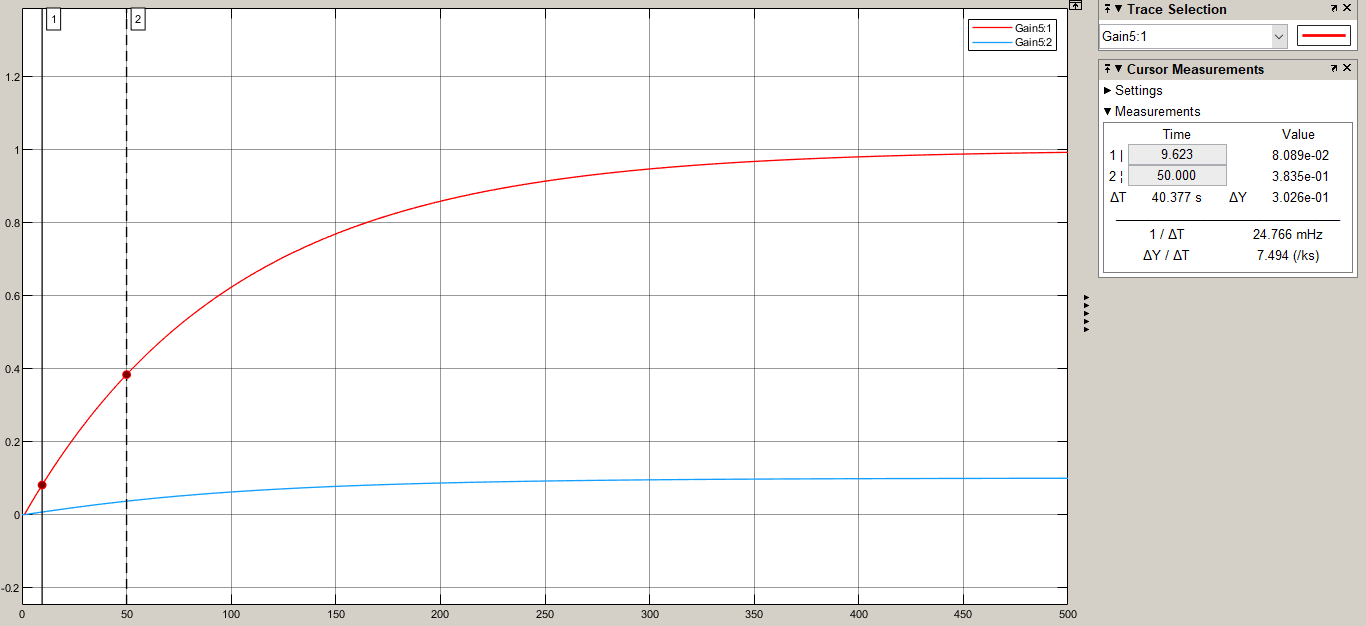

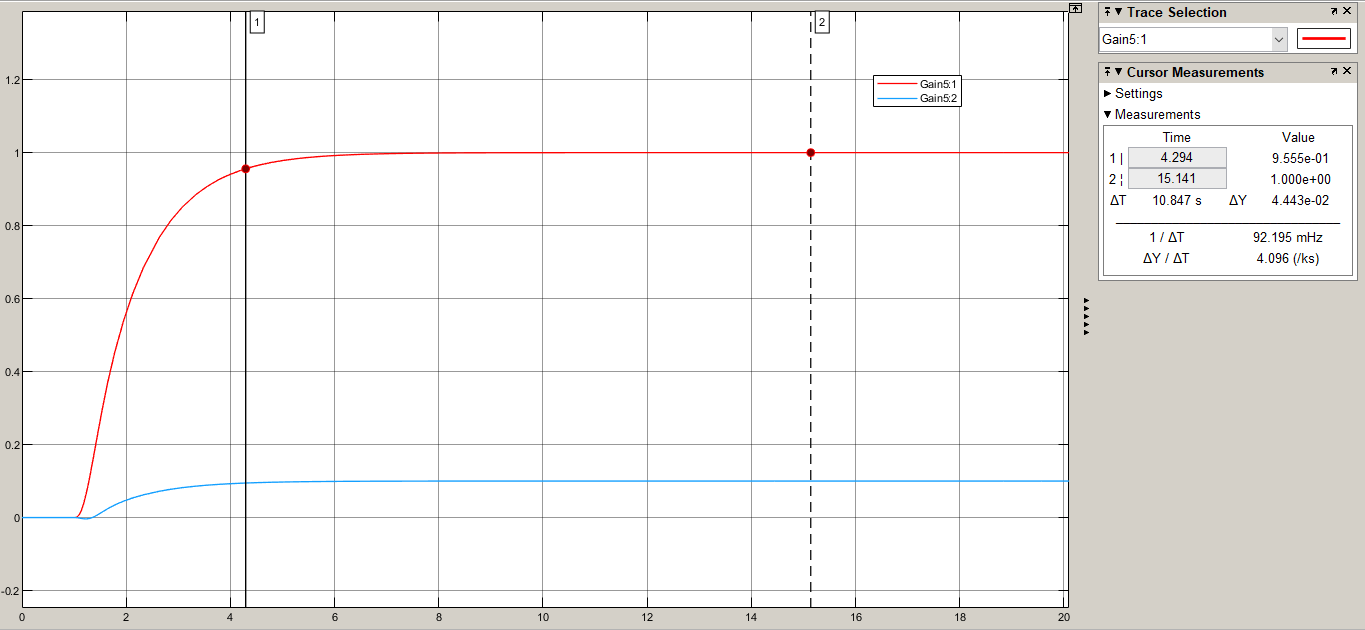

Se puede observar también que al aumentar el valor de  $\rho \;$penalizo más el control 

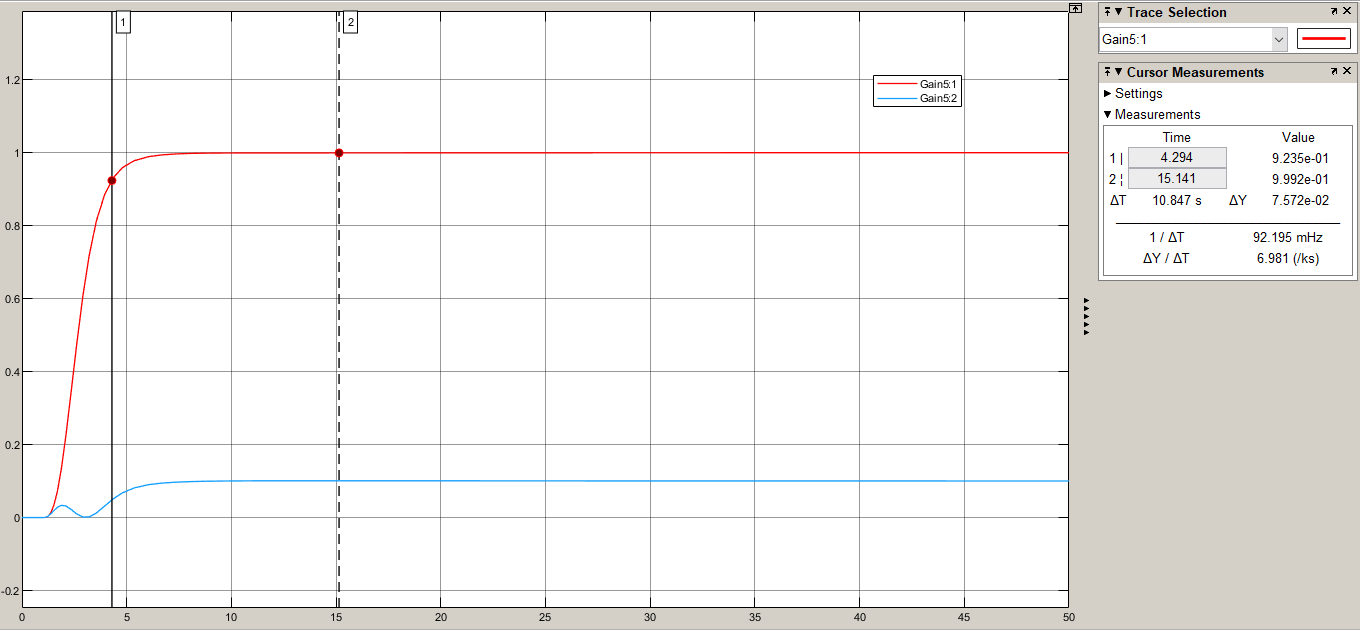

El sistema responde a perturbaciones

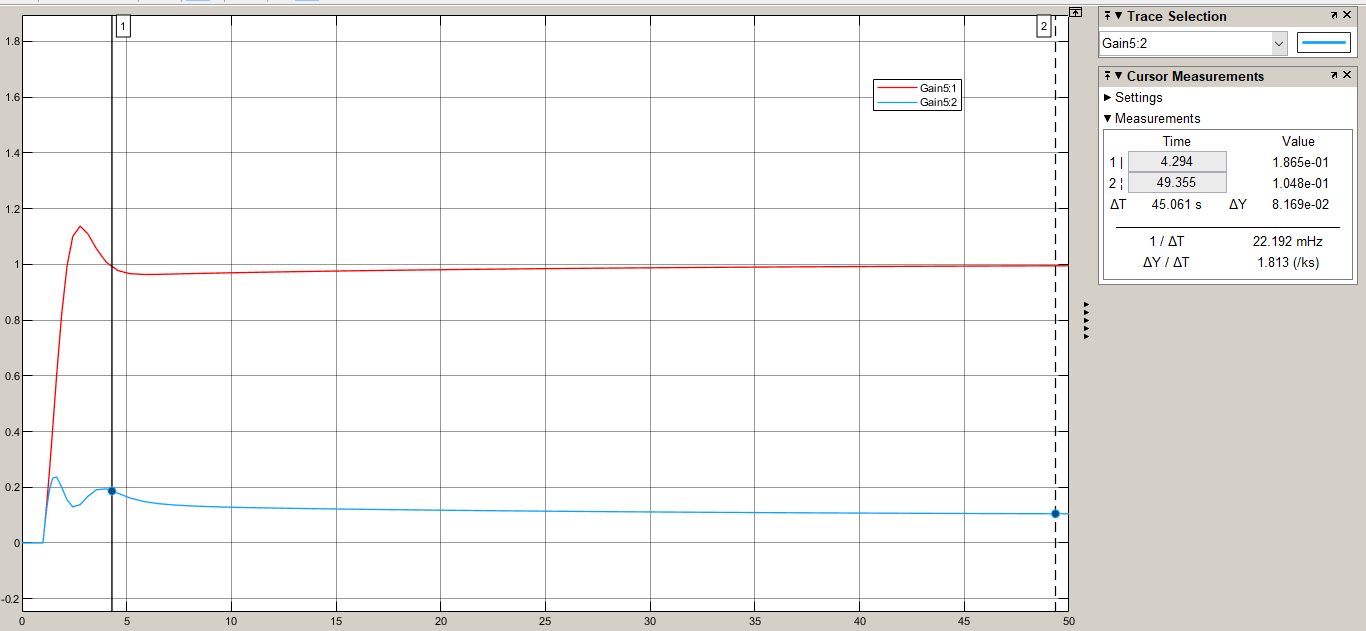

El esquema básico de la planta junto con la primera versión del controlador es el siguiente:

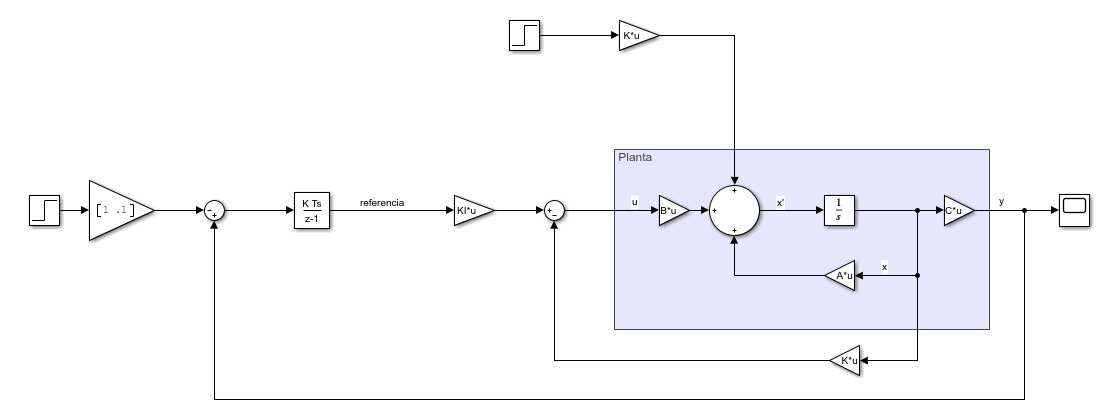

### Filtro de Kalman

Se aplica el filtro de Kalman para tener en cuenta el posible ruido en el sistema. Se obtiene la matriz L y se agrega en el estimador. 

%Covarianzas de ruido de proceso y de ruido de sensor
Qk_coef = 1.5;
% Qk = Qk_coef*eye(2);
Qk = [3 0;0 1.5]

Qk =     3.0000         0
         0    1.5000


%Qk = [1.5 0; 0 1.1];
%Qk = 1;
Rk = [0.0001 0; 0 0.0001]; %Funciona mejor que la covarianza igual a 1
%Rk = [1 0; 0 1];
[kalmf,L,~,Mx,Z] = kalman(sys,Qk,Rk)

kalmf =
 
  A = 
            x1_e     x2_e     x3_e     x4_e     x5_e
   x1_e  -0.0558     0.08   -0.997   -1.748    11.36
   x2_e    -3.05   -0.465    0.388   -24.33    5.219
   x3_e    0.598   -0.318   -0.115    12.56   -55.66
   x4_e        0        1        0   -6.901    1.022
   x5_e        0        0        1    1.022    -10.5
 
  B = 
             y1      y2
   x1_e   1.789  -11.36
   x2_e   24.33  -5.219
   x3_e  -12.56   55.66
   x4_e   6.901  -1.022
   x5_e  -1.022    10.5
 
  C = 
         x1_e  x2_e  x3_e  x4_e  x5_e
   y1_e     0     0     0     1     0
   y2_e     0     0     0     0     1
   x1_e     1     0     0     0     0
   x2_e     0     1     0     0     0
   x3_e     0     0     1     0     0
   x4_e     0     0     0     1     0
   x5_e     0     0     0     0     1
 
  D = 
         y1  y2
   y1_e   0   0
   y2_e   0   0
   x1_e   0   0
   x2_e   0   0
   x3_e   0   0
   x4_e   0   0
   x5_e   0   0
 
Input groups:              
       Name        Channels
    

L =     1.7893  -11.3574
   24.3322   -5.2191
  -12.5615   55.6563
    6.9008   -1.0218
   -1.0218   10.5009



Mx =

     []


Z =

     []



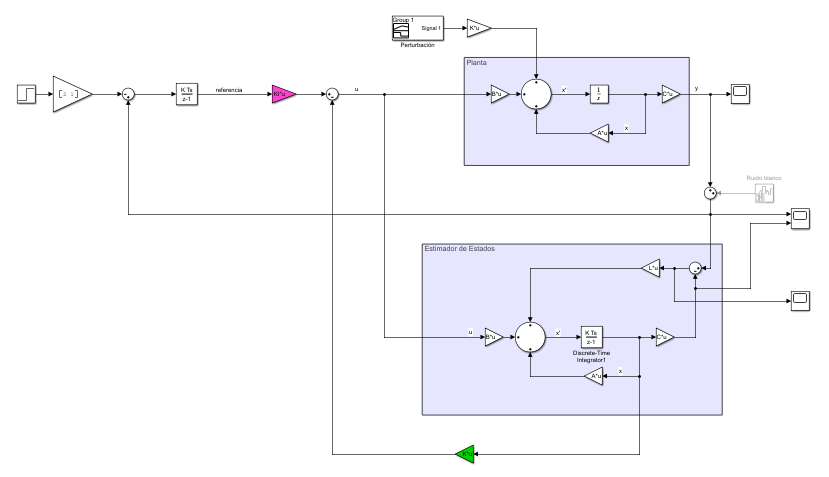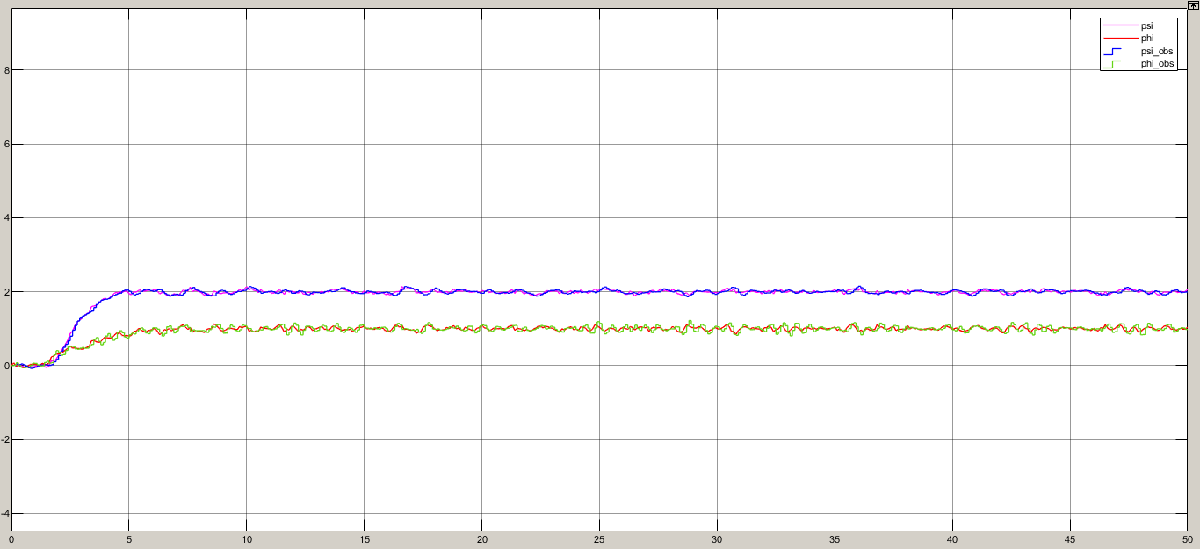

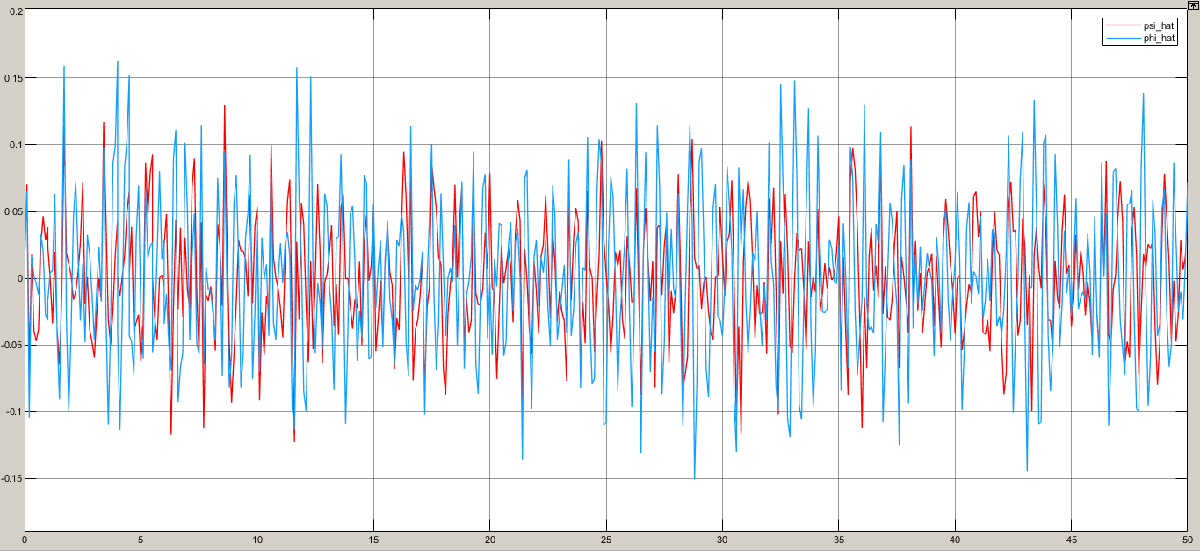

Para pequeñas perturbaciones, el sistema responde de la siguiente manera:

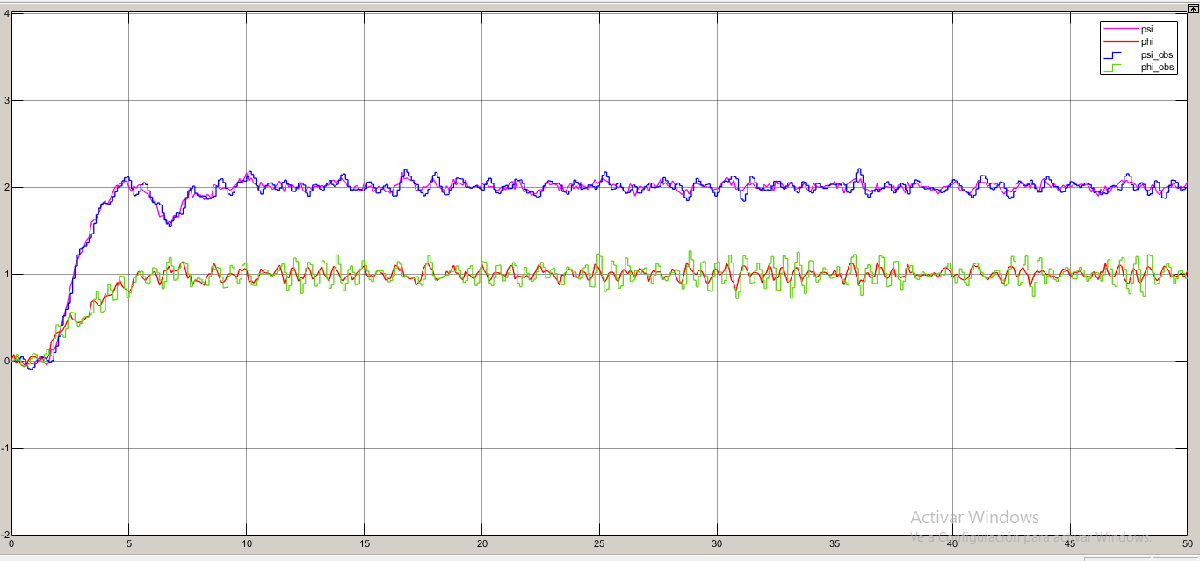

Ahora, cuando se agrega una perturbación mayor se tiene el siguiente comportamiento:

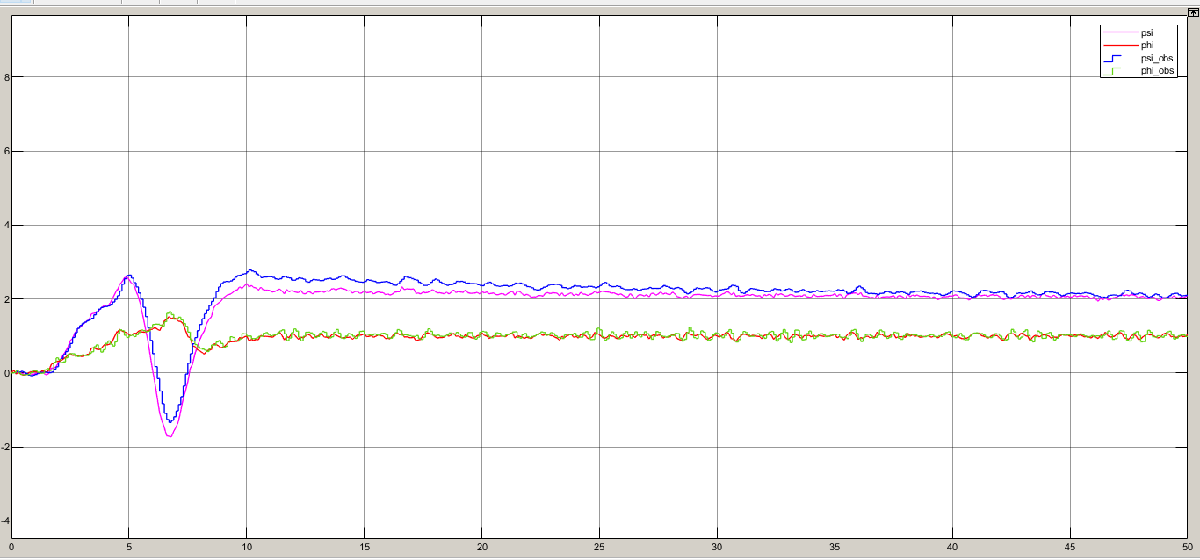

Al aplicar una perturbación de carga de tipo escalón se observa que el valor de la posición tiene un error de estado estacionario. Esto se debe a que el estimador no tiene rechazo a perturbaciones porque no se realimenta la perturbación. Una manera de solucionar esto es realimentando la perturbaci ́on al modelo de la planta del observador, pero esta es una soluci ́on muy costosa. Otra manera para  solucionarlo sin necesidad de utilizar un sensor es agregando un integrador en el modelo de la planta del observador. Además de lo anteriormente mencionado se puede considerar usar el filtro de Kalman extendido.

Se opta por agregar una acción integral. La obtención de la ganancia será por el método de Ackerman. Los polos a lazo cerrado se obtienen de la siguiente forma:

s = sym('s');
I = eye(5);
MA = s*I-A+L*C

$$MA = \left(\begin{array}{ccccc} s+\frac{279}{5000} & -\frac{2}{25} & \frac{997}{1000} & \frac{983904696260836427}{562949953421312000} & -\frac{1998591112277977603}{175921860444160000}\\ \frac{61}{20} & s+\frac{93}{200} & -\frac{97}{250} & \frac{856113259459105}{35184372088832} & -\frac{5876171111344157}{1125899906842624}\\ -\frac{299}{500} & \frac{159}{500} & s+\frac{23}{200} & -\frac{7071471112361203}{562949953421312} & \frac{7832934699072043}{140737488355328}\\ 0 & -1 & 0 & s+\frac{7769556391349519}{1125899906842624} & -\frac{1150415221661881}{1125899906842624}\\ 0 & 0 & -1 & -\frac{4601660886647731}{4503599627370496} & s+\frac{2955737555856415}{281474976710656} \end{array}\right)$$

DET=det(s*I-A+L*C) == 0

$$DET = s^{5}+\frac{12692721109716074587\,s^{4}}{703687441776640000}+\frac{12955544203707293100069579719928031069\,s^{3}}{79228162514264337593543950336000000}+\frac{278942627166400443055969983734559567068071\,s^{2}}{396140812571321687967719751680000000000}+\frac{4774011385198566438175810634188935636491273\,s}{3169126500570573503741758013440000000000}+\frac{331105390829211583339848074751283718016759}{5070602400912917605986812821504000000000}=0$$


%poles(DET,s)
solx = solve(DET,s)

$$solx = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right)\\ \mathrm{root}\left(\sigma_{1},z,4\right)\\ \mathrm{root}\left(\sigma_{1},z,5\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{5}+\frac{12692721109716074587\,z^{4}}{703687441776640000}+\frac{12955544203707293100069579719928031069\,z^{3}}{79228162514264337593543950336000000}+\frac{278942627166400443055969983734559567068071\,z^{2}}{396140812571321687967719751680000000000}+\frac{4774011385198566438175810634188935636491273\,z}{3169126500570573503741758013440000000000}+\frac{331105390829211583339848074751283718016759}{5070602400912917605986812821504000000000} \end{array}$$

y=1;
for i=1:5
    y = y*MA(i,i)
end

$$y = s+\frac{279}{5000}$$

$$y = \left(s+\frac{93}{200}\right)\,\left(s+\frac{279}{5000}\right)$$

$$y = \left(s+\frac{23}{200}\right)\,\left(s+\frac{93}{200}\right)\,\left(s+\frac{279}{5000}\right)$$

$$y = \left(s+\frac{7769556391349519}{1125899906842624}\right)\,\left(s+\frac{23}{200}\right)\,\left(s+\frac{93}{200}\right)\,\left(s+\frac{279}{5000}\right)$$

$$y = \left(s+\frac{2955737555856415}{281474976710656}\right)\,\left(s+\frac{7769556391349519}{1125899906842624}\right)\,\left(s+\frac{23}{200}\right)\,\left(s+\frac{93}{200}\right)\,\left(s+\frac{279}{5000}\right)$$

soly=solve(y,s)

$$soly = \left(\begin{array}{c} -\frac{2955737555856415}{281474976710656}\\ -\frac{7769556391349519}{1125899906842624}\\ -\frac{93}{200}\\ -\frac{23}{200}\\ -\frac{279}{5000} \end{array}\right)$$

Se extiende el sistema, creando una nueva variable de estado $z\left(t\right)=K_i \int e\left(t\right)$ siendo e(t) el error.

El sistema aumentado del observador tiene la siguiente forma:


$$\overset{\ldotp }{x} =\left\lbrack \begin{array}{cc}
A & 1\\
\textrm{LC} & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
z
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\\
0
\end{array}\right\rbrack u+\left\lbrack \begin{array}{c}
L\\
K_i 
\end{array}\right\rbrack e$$


Ahat = [A ones(5,2);
    C*L zeros(2,5)];
Bhat = [B; zeros(2,2)];
% Chat = [C*L zeros(2,5)];
% Dhat =zeros(2);
% sys_obs = ss(Ahat,Bhat,Chat,Dhat)
% [kalmfhat,Lhat,~,Mxhat,Zhat] = kalman(sys_obs,Qk,Rk)
 s = sym('s');
I = eye(7);
DET=det(s*I-Ahat) == 0

$$DET = s^{7}+\frac{3179\,s^{6}}{5000}-\frac{1006882759882088574269\,s^{5}}{70368744177664000000}+\frac{9401406345900956795147429\,s^{4}}{351843720888320000000000}-\frac{72900953215465107872119\,s^{3}}{2199023255552000000000}-\frac{10726101614113104587821\,s^{2}}{1407374883553280000000000}=0$$

% 
% %poles(DET,s)
solx = solve(DET,s)

$$solx = \begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right)\\ \mathrm{root}\left(\sigma_{1},z,4\right)\\ \mathrm{root}\left(\sigma_{1},z,5\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{5}+\frac{3179\,z^{4}}{5000}-\frac{1006882759882088574269\,z^{3}}{70368744177664000000}+\frac{9401406345900956795147429\,z^{2}}{351843720888320000000000}-\frac{72900953215465107872119\,z}{2199023255552000000000}-\frac{10726101614113104587821}{1407374883553280000000000} \end{array}$$

%Busco polos de la forma
p = [-10.4561 -5.8720 -0.4650 -0.1150 -0.0558 -40 -50]

p =   -10.4561   -5.8720   -0.4650   -0.1150   -0.0558  -40.0000  -50.0000


Lhat = place(Ahat,Bhat,p)

Lhat =   457.9326  396.3305   81.4371 -241.3731  216.3085  344.2556  380.9357
  459.8767   25.1916  -88.0313   29.1726  -20.4669   91.4813   80.3366
